clc;

% Start the timer
tic

## Properties

% trivial properties
numTheta = 1000;
theta = linspace(-pi+2*pi/numTheta, pi, numTheta);

% obstacles array
Obstacles = struct('x', [], 'y', []);

% binary map
Map.res = 0.1;
Map.limit = struct( ...
    'x', struct('min', -10, 'max', 10), ...
    'y', struct('min', -10, 'max', 10)  ...
    );
Map.map = zeros( ...
    round((Map.limit.y.max-Map.limit.y.min)/Map.res) + 1, ...
    round((Map.limit.x.max-Map.limit.x.min)/Map.res) + 1  ...
    );

% mobile robot
Robot.length = 0.78;
Robot.width  = 0.51;
Robot.position.x = 0;
Robot.position.y = 0;
Robot.orientation = 0;
[Robot.body.x, Robot.body.y] = rectangleObstacle( ...
    Robot.position.x, Robot.position.y, ...
    Robot.width, Robot.length, Robot.orientation);
Robot.velocity = struct('linear', 0, 'angular', 0);
Robot.velocityLimit = struct('linear', 0.7, 'angular', 0.5);

% assistive controller 
Assist.velocity = struct('linear', 0, 'angular', 0);
Assist.kx = 50;     % [tune]
Assist.ky = 50;     % [tune]
Assist.kw = 0.1;    % [tune]

% static virtual zone (SVZ)
SVZ.x = zeros(1, numTheta);
SVZ.y = zeros(1, numTheta);
SVZ.a = 0;      % semi-major axis
SVZ.b = 0;      % semi-minor axis
SVZ.ka = Robot.length * 10;     % gain for a
SVZ.kb = Robot.width * 10;      % gain for b
SVZ.dist = zeros(1, numTheta);

% deformable virtual zone (DVZ)
DVZ.x = zeros(1, numTheta);
DVZ.y = zeros(1, numTheta);
DVZ.a = 0;      % semi-major axis
DVZ.b = 0;      % semi-minor axis
DVZ.ka = Robot.length * 10;
DVZ.kb = Robot.width * 10;
DVZ.dist = zeros(1, numTheta);

## Obstacle definition & map initialization

% Set up the static obstacles

idx = 1;
% [Obstacles(idx).x, Obstacles(idx).y] = rectangleObstacle(0, 2, 1, 2, 0);    idx = idx + 1;
[Obstacles(idx).x, Obstacles(idx).y] = rectangleObstacle(3, -2, 1, 2, 0);   idx = idx + 1;

% Initialize the map
for idx = 1:length(Obstacles)
    [~, j_UR] = coord2mat(Obstacles(idx).x(3), Obstacles(idx).y(3), ...
        Map.limit.x, Map.limit.y, Map.res);
    [i_UL, j_UL] = coord2mat(Obstacles(idx).x(4), Obstacles(idx).y(4), ...
        Map.limit.x, Map.limit.y, Map.res);
    [i_BL, ~] = coord2mat(Obstacles(idx).x(5), Obstacles(idx).y(5), ...
        Map.limit.x, Map.limit.y, Map.res);
    Map.map(i_UL:i_BL, j_UL:j_UR) = ones(length(i_UL:i_BL), length(j_UL:j_UR));
end
clear j_UR i_UL j_UL i_BL;

## Calculate SVZ & DVZ

% pre-defined SVZ
SVZ.a = 7.8;
SVZ.b = 5.1;
SVZ.dist = ((SVZ.a * cos(theta)).^2 + (SVZ.b * sin(theta)).^2).^0.5;
SVZ.x = Robot.position.x ...
    + SVZ.a * cos(Robot.orientation) * cos(theta) ...
    - SVZ.b * sin(Robot.orientation) * sin(theta);
SVZ.y = Robot.position.y ...
    + SVZ.a * sin(Robot.orientation) * cos(theta) ...
    + SVZ.b * cos(Robot.orientation) * sin(theta);

% pre-defined DVZ (the same as SVZ)
DVZ.x = SVZ.x;
DVZ.y = SVZ.y;
DVZ.dist = SVZ.dist;

% Calculate the position of obstacles nearby
numBeamPoint = numTheta / 10;
beam.x = zeros(numTheta, numBeamPoint);
beam.x(:, numBeamPoint) = (SVZ.dist .* cos(theta+Robot.orientation)).';
beam.x(:, 2:numBeamPoint-1) = ((SVZ.dist/(numBeamPoint-1)) ...
    .* cos(theta+Robot.orientation)).' .* (1:numBeamPoint-2);
beam.x = beam.x + Robot.position.x;

beam.y = zeros(numTheta, numBeamPoint);
beam.y(:, numBeamPoint) = (SVZ.dist .* sin(theta+Robot.orientation)).';
beam.y(:, 2:numBeamPoint-1) = ((SVZ.dist/(numBeamPoint-1)) ...
    .* sin(theta+Robot.orientation)).' .* (1:numBeamPoint-2);
beam.y = beam.y + Robot.position.y;

[beam.i, beam.j] = coord2mat(beam.x, beam.y, Map.limit.x, Map.limit.y, Map.res);
beamIndices = sub2ind(size(Map.map), beam.i, beam.j);
beam.point = Map.map(beamIndices);
for idx = 1:numTheta
    obstacleIndices = find(beam.point(idx,:) == 1);
    if ~isempty(obstacleIndices)
        obs.index = beamIndices(idx, obstacleIndices(1));
        [obs.i, obs.j] = ind2sub(size(Map.map), obs.index);
        [obs.x, obs.y] = mat2coord(obs.i, obs.j, ...
            Map.limit.x, Map.limit.y, Map.res);
        DVZ.x(idx) = obs.x;
        DVZ.y(idx) = obs.y;
        DVZ.dist(idx) = ((obs.x - Robot.position.x)^2 ...
            + (obs.y - Robot.position.y)^2)^0.5;
    end
end
clear obs;

## Calculate metrics

% intrusion ratio (I_D)
ID_func = (SVZ.dist - DVZ.dist) ./ (DVZ.dist);
ID = trapz(theta, ID_func);

% average angle of obstacles (Theta_D)
AverageAngle_num_func = (SVZ.dist - DVZ.dist) .* theta;
AverageAngle_den_func = (SVZ.dist - DVZ.dist);
AverageAngle = trapz(theta, AverageAngle_num_func)/trapz(theta, AverageAngle_den_func) + Robot.orientation;

% Jacobian function of x axis (Jx)
Jx_func = -(Robot.position.x - DVZ.x)./(SVZ.dist .* DVZ.dist);
Jx = trapz(theta, Jx_func);

% Jacobian function of y axis (Jy)
Jy_func = -(Robot.position.y - DVZ.y)./(SVZ.dist .* DVZ.dist);
Jy = trapz(theta, Jy_func);

## Assistive controller

Assist.velocity.linear = -Assist.kx * Jx * cos(Robot.orientation) - Assist.ky * Jy * sin(Robot.orientation);
Assist.velocity.angular = -Assist.kw * (Robot.orientation + AverageAngle);

## Adaption law

## Plotting

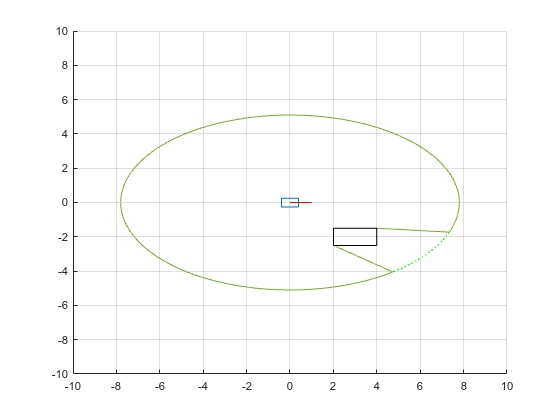

axis([-10 10 -10 10]); hold on; grid on;

% Plot the body of the mobile robot
plot(Robot.body.x, Robot.body.y);

% Plot the DVZ field
plot(SVZ.x, SVZ.y, ':', 'Color', '#00FF00');
plot(DVZ.x, DVZ.y, '-', 'Color', '#77AC30');

% Plot the heading orientation
plot([Robot.position.x, Robot.position.x+cos(Robot.orientation)], ...
    [Robot.position.y, Robot.position.y+sin(Robot.orientation)], ...
    "Color", 'r' ...
    );

% Plot the obstacles
for idx = 1:length(Obstacles)
    plot(Obstacles(idx).x, Obstacles(idx).y, 'Color', 'k');
end

## Evaluation

% Stop the timer
elapsedTime = toc;

% Display the elapsed time
fprintf('Elapsed time: %.4f seconds\n', elapsedTime);

Elapsed time: 0.1310 seconds


## Clear

clear idx;

## Functions

Convert 2D coordinates to 2D matrix indices

function [i,j] = coord2mat(x, y, xLim, yLim, res)
if any(any(x < xLim.min)) || any(any(x > xLim.max))
    error(['[coord2mat] All elements of x' ...
        ' must be within the limit [%lf ~ %lf]'], xLim.min, xLim.max);
end

if any(any(y < yLim.min)) || any(any(y > yLim.max))
    error(['[coord2mat] All elements of y' ...
        ' must be within the limit [%lf ~ %lf]'], yLim.min, yLim.max);
end

i = round((yLim.max-y)/res)+1;
j = round((xLim.max+x)/res)+1;
end

% Convert 2D matrix indices to 2D coordinates
function [x,y] = mat2coord(i, j, xLim, yLim, res)
if any(any(i < 1)) || any(any(i > (yLim.max-yLim.min)/res+1))
    error(['[mat2coord] All elements in i' ...
        ' must be within the boundary [%lf ~ %lf]'], 1, (yLim.max-yLim.min)/res+1);
end

if any(any(j < 1)) || any(any(j > (xLim.max-xLim.min)/res+1))
    error(['[mat2coord] All elements in j' ...
        ' must be within the boundary [%lf ~ %lf]'], 1, (xLim.max-xLim.min)/res+1);
end

x =  (j-1)*res - xLim.max;
y = -(i-1)*res + yLim.max;
end

% Create rectangle obstacles
function [x, y] = rectangleObstacle(centerX, centerY, height, width, theta)
% Check if the input values are valid
if height <= 0 || width <= 0
    error('Height and width must be positive values.');
end

% Assume the bottom-left corner of the rectangle is at the origin (0,0)
originalX = centerX + [-width/2, width/2, width/2, -width/2, -width/2];
originalY = centerY + [-height/2, -height/2, height/2, height/2, -height/2];
x = cos(theta) * originalX - sin(theta) * originalY;
y = sin(theta) * originalX + cos(theta) * originalY;
end